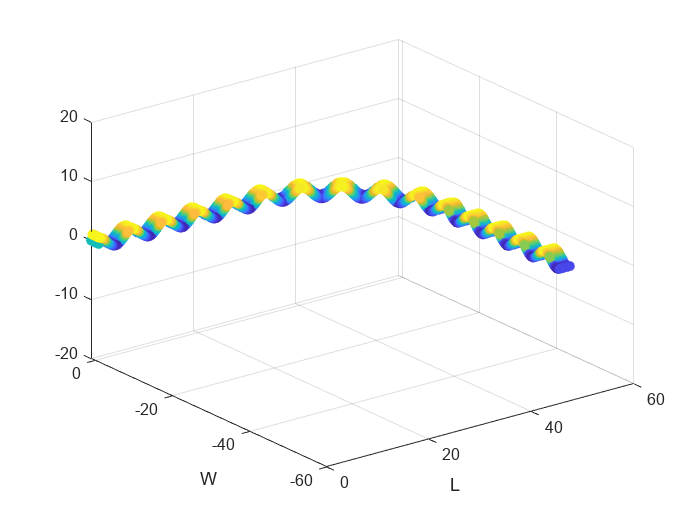

U1 = U.sc;

x = Coordinate(:,1); y = Coordinate(:,2);
T = 2*pi/Cf;
har = @(t) exp(-1i*Cf*t);

t = linspace(0,2*T,100);
maxU1 = max(abs(U1));

figure
for it = 1:length(t)
	u = U1*har(t(it));
% 	u = u./maxU1;
	scatter1 = scatter3(x,y,real(u),36,real(u),'filled',MarkerFaceColor='flat');
		zlim([-max(abs(U1)) max(abs(U1))])
	zlim(20*[-1 1]);
	xlabel("L");ylabel("W");
	pause(1e-2)
end


% error("第一段程序执行完毕")

云图

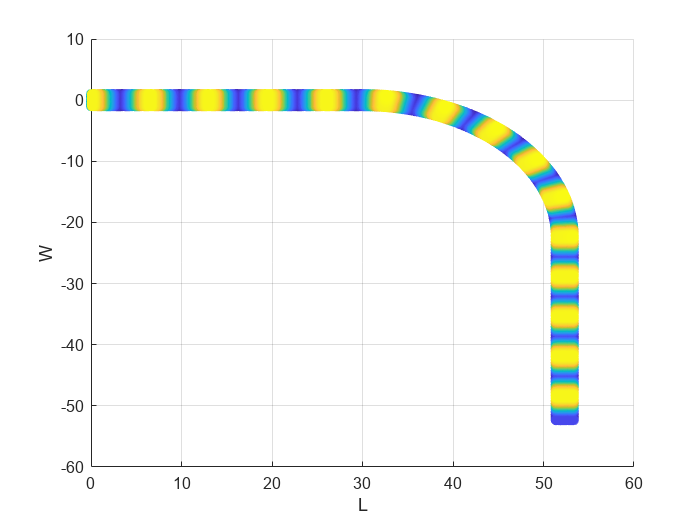

figure
for it = 1:length(t)
	u = U1*har(t(it));
	scatter2 = scatter3(x,y,real(u),36,real(u),'filled');
	zlim([-max(abs(U1)) max(abs(U1))])
	view(2)
	xlabel("L");ylabel("W");
	pause(0.0001)
end